filePath = fullfile(getenv('USERPROFILE'), 'Desktop', 'trainingData.csv');
data = readtable(filePath);
selectedData = data(1:200, 10:20);
figure;
uitable('Data', selectedData.Variables, 'ColumnName', selectedData.Properties.VariableNames);
title('First 100 Rows of Columns 15 and 16 of the Dataset');
saveas(gcf, fullfile(getenv('USERPROFILE'), 'Desktop', 'SelectedDatasetHead.png'));
features = selectedData(:, 1);  
target = selectedData(:, 2);   
X = table2array(features);
Y = table2array(target);
if iscell(Y)
    Y = categorical(Y);
end
cv = cvpartition(height(selectedData), 'HoldOut', 0.3);
XTrain = X(training(cv), :);
YTrain = Y(training(cv), :);
XTest = X(test(cv), :);
YTest = Y(test(cv), :);
SVMModel = fitcecoc(XTrain, YTrain, 'Learners', 'linear');
save(fullfile(getenv('USERPROFILE'), 'Desktop', 'SVMModel.mat'), 'SVMModel');
YPred = predict(SVMModel, XTest);
accuracy = sum(YPred == YTest) / numel(YTest);
fprintf('Accuracy: %.2f%%\n', accuracy * 100);

Accuracy: 95.00%


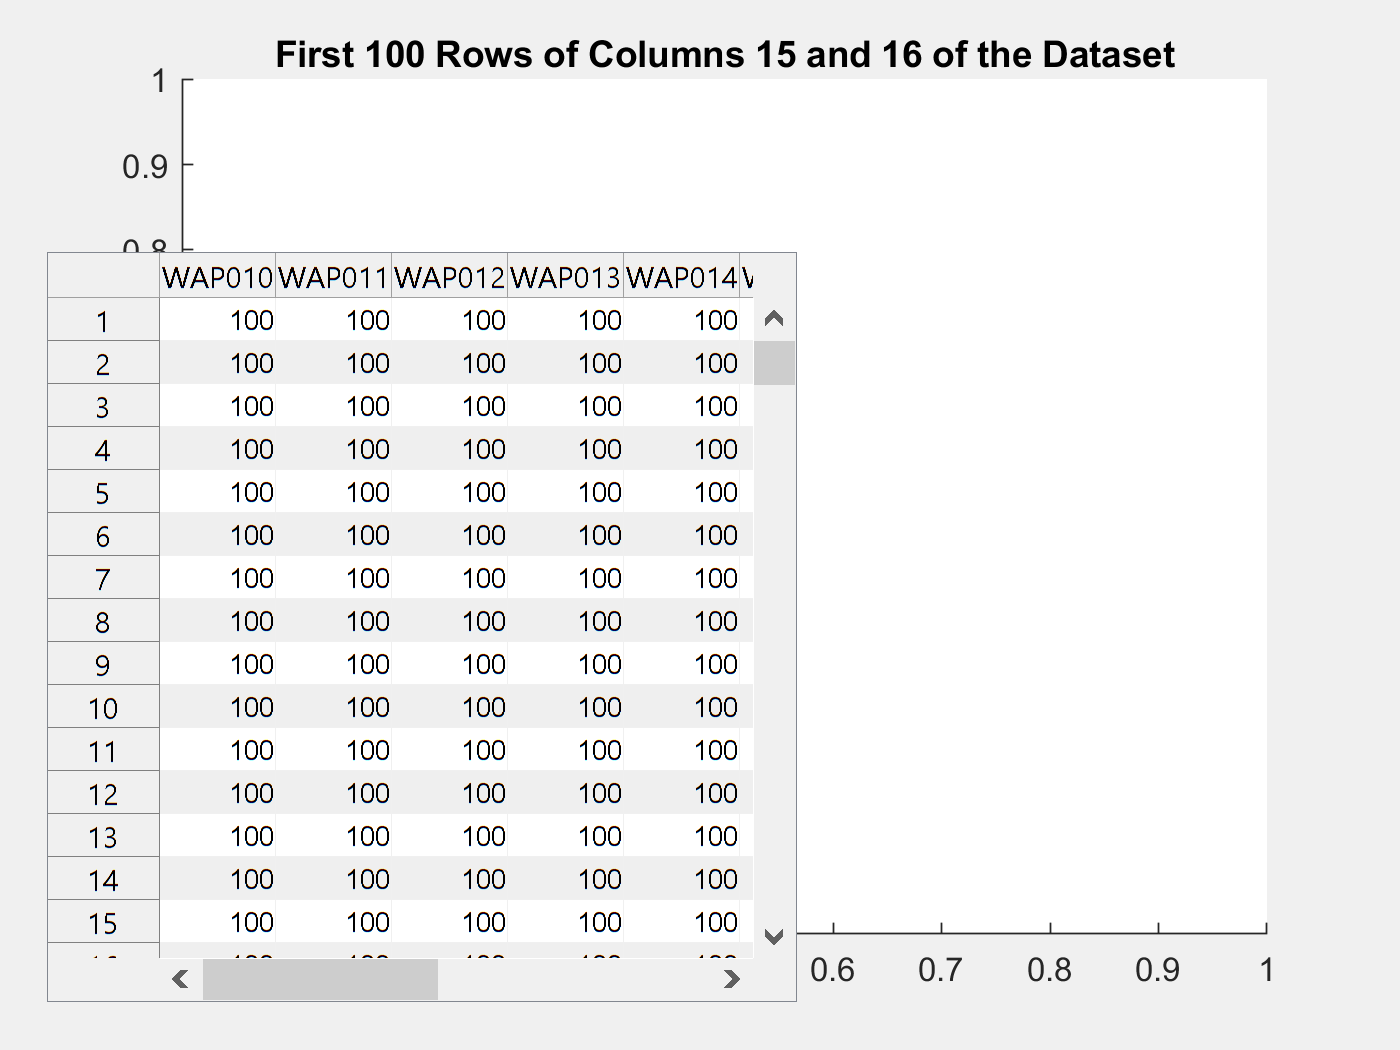

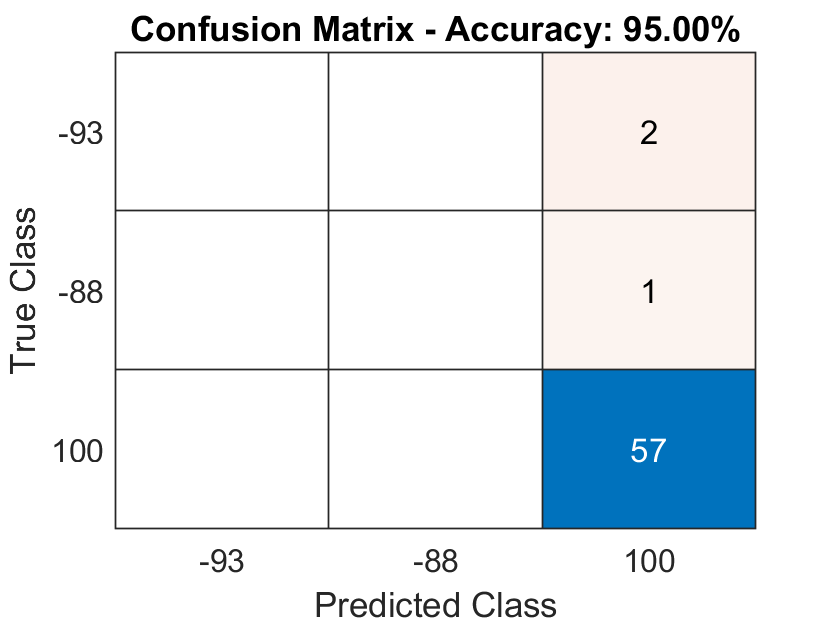


figure;
confusionchart(YTest, YPred);
title(sprintf('Confusion Matrix - Accuracy: %.2f%%', accuracy * 100));
saveas(gcf, fullfile(getenv('USERPROFILE'), 'Desktop', 'ConfusionMatrix.png'));

Mean Error: -9.57


Median Error: 0.00


Standard Deviation of Error: 42.06


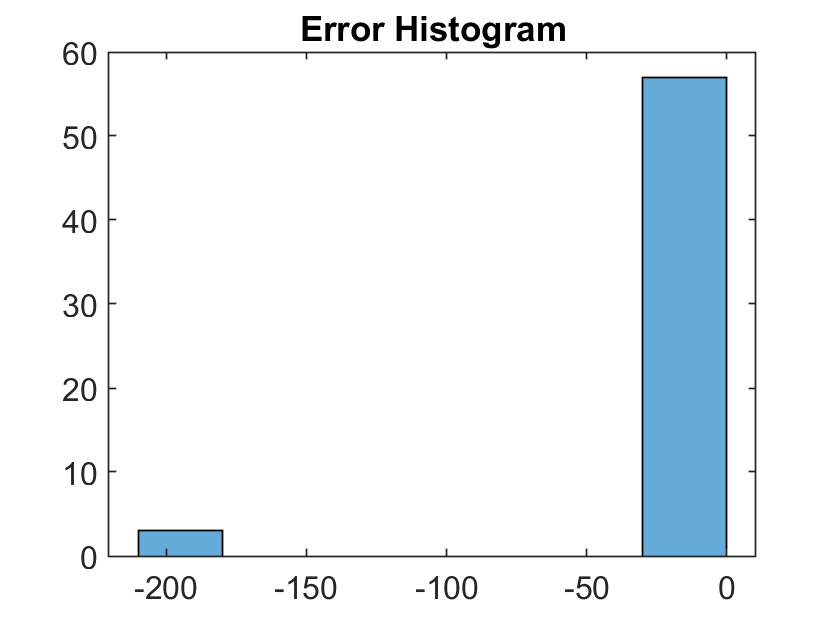


if ~iscategorical(Y)
    errors = YTest - YPred;
    meanError = mean(errors);
    medianError = median(errors);
    stdError = std(errors);
  
    fprintf('Mean Error: %.2f\n', meanError);
    fprintf('Median Error: %.2f\n', medianError);
    fprintf('Standard Deviation of Error: %.2f\n', stdError);
    
    figure;
    histogram(errors);
    title('Error Histogram');
    saveas(gcf, fullfile(getenv('USERPROFILE'), 'Desktop', 'ErrorHistogram.png'));
end